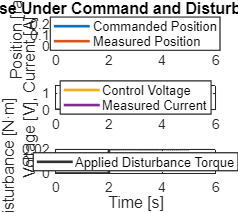

t = out.DataSim.Time;
y = squeeze(out.DataSim.Data);

theta_cmd  = y(:,1);
v_cmd      = y(:,2);
theta_meas = y(:,3);
i_meas     = y(:,4);
tau_dist   = y(:,5);

figure('Color','w','Position',[100 100 900 650]);

% subplot(2,1,1);
% plot(t, theta_cmd,  'LineWidth', 2.2, 'Color', [0.00 0.45 0.74]); hold on;
% plot(t, theta_meas, 'LineWidth', 2.2, 'Color', [0.85 0.33 0.10]);
% grid on;
% ylabel('Position [rad]');
% title('Simulink Actuator Step Response');
% legend('Commanded Position','Measured Position','Location','best');
% set(gca,'FontSize',12,'LineWidth',1.0);
% 
% subplot(2,1,2);
% plot(t, v_cmd, 'LineWidth', 2.2, 'Color', [0.93 0.69 0.13]); hold on;
% plot(t, i_meas,'LineWidth', 2.0, 'Color', [0.49 0.18 0.56]);
% grid on;
% xlabel('Time [s]');
% ylabel('Control Effort [V and A]');
% legend('Control Voltage [V]','Measured Current [A]','Location','best');
% set(gca,'FontSize',12,'LineWidth',1.0);
% 
% exportgraphics(gcf,'D:\Work\SimulinkPortfolio\SpaceActuator\actuator_step_response.png','Resolution',300);

figure('Color','w','Position',[100 100 950 850]);

subplot(3,1,1);
plot(t, theta_cmd,  'LineWidth', 2.2, 'Color', [0.00 0.45 0.74]); hold on;
plot(t, theta_meas, 'LineWidth', 2.2, 'Color', [0.85 0.33 0.10]);
grid on;
ylabel('Position [rad]');
title('Actuator Response Under Command and Disturbance Torque with PID');
legend('Commanded Position','Measured Position','Location','best');
set(gca,'FontSize',12,'LineWidth',1.0);

subplot(3,1,2);
plot(t, v_cmd, 'LineWidth', 2.2, 'Color', [0.93 0.69 0.13]); hold on;
plot(t, i_meas,'LineWidth', 2.2, 'Color', [0.49 0.18 0.56]);
grid on;
ylabel('Voltage [V], Current [A]');
legend('Control Voltage','Measured Current','Location','best');
set(gca,'FontSize',12,'LineWidth',1.0);

subplot(3,1,3);
plot(t, tau_dist, 'LineWidth', 2.2, 'Color', [0.20 0.20 0.20]);
grid on;
xlabel('Time [s]');
ylabel('Disturbance [N·m]');
legend('Applied Disturbance Torque','Location','best');
set(gca,'FontSize',12,'LineWidth',1.0);

exportgraphics(gcf,'D:\Work\SimulinkPortfolio\SpaceActuator\actuator_disturbance_response_PID.png','Resolution',300);